%Inverse Kinematics
robot.ikineType = 'nooffset'

 
robot = 
 
AltusBot:: 6 axis, RRRRRR, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.06781|      0.038|     1.5708|          0|
|  2|         q2|          0|        0.3|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|        0.2|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.09), RPY/xyz = (0, 0, 0) deg               
 


qs = [0 pi/2 0 0 0 0]; %ready angle(straight up)
Ts = robot.fkine(qs) %Must Match Below qi2 T matrix

 

Ts = 
         0         0         1     0.328
         0        -1         0         0
         1         0         0    0.3678
         0         0         0         1


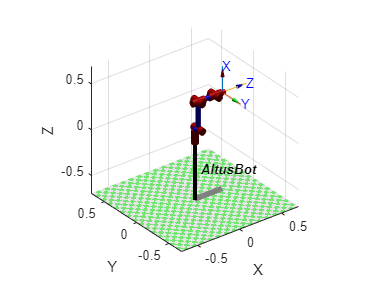

%Pose I want IK solution to Get
robot.plot(qs)

T2 = SE3(0.338, 0, 0.3678) 

 

T2 = 
         1         0         0     0.338
         0         1         0         0
         0         0         1    0.3678
         0         0         0         1


q2 = [0 pi/2 0 0 0 0];
robot.plot(q2)

q2_deg = q2*180/pi

q2_deg =      0    90     0     0     0     0


q3_deg = [-34.0 49 -7.2 0 -39.6 0]

q3_deg =   -34.0000   49.0000   -7.2000         0  -39.6000         0


q3 = q3_deg*pi/180

q3 =    -0.5934    0.8552   -0.1257         0   -0.6912         0


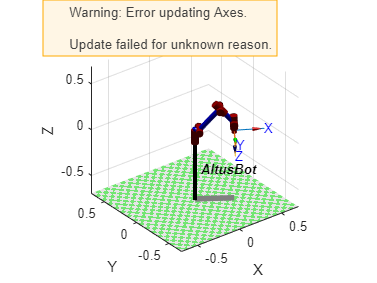

robot.plot(q3)

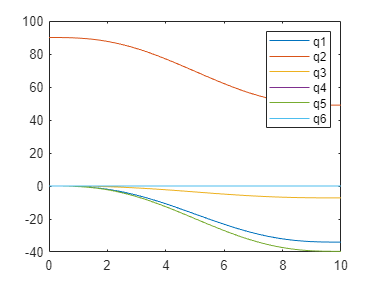

t = [0:0.05:10]; % over 2 sec period in 50ms increments
[qh,qd,qdd]=jtraj(q2,q3,t); %pos,vel,accel
qh = qh*180/pi;
plot(t, qh) %plots all 6 joint angles over t
legend(["q1","q2","q3","q4","q5","q6"])

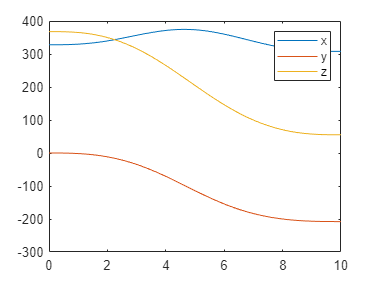

qh = qh*pi/180;
T = robot.fkine(qh);
p = T.transl; % gets only translational part of transformation matrix T
p = p*1000;
plot(t,p) %plots xyz vs time
legend(["x","y","z"])

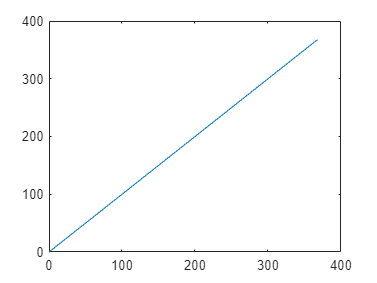

plot(p(1,:),p(2,:)) %plots path of end-effector in xy plane

serial_send("OG",s);

OG


q3_deg_rounded = round(q3_deg,2);
stringData = q3_deg_rounded(1) + "," + q3_deg_rounded(2) + "," + q3_deg_rounded(3) + "," + q3_deg_rounded(4) + "," + q3_deg_rounded(5) + "," + q3_deg_rounded(6) ;
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,-34,49,-7.2,0,-39.6,0"

serial_send(stringData,s);

MJ,-34,49,-7.2,0,-39.6,0



pause(10)

serial_send("CG",s);

CG


pause(1)

q2_deg_rounded = round(q2_deg,2);
stringData = q2_deg_rounded(1) + "," + q2_deg_rounded(2) + "," + q2_deg_rounded(3) + "," + q2_deg_rounded(4) + "," + q2_deg_rounded(5) + "," + q2_deg_rounded(6); 
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,0,90,0,0,0,0"

serial_send(stringData,s);

MJ,0,90,0,0,0,0



pause(10)

q3_deg_rounded = round(q3_deg,2);
stringData = q3_deg_rounded(1) + "," + q3_deg_rounded(2) + "," + q3_deg_rounded(3) + "," + q3_deg_rounded(4) + "," + q3_deg_rounded(5) + "," + q3_deg_rounded(6) ;
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,-34,49,-7.2,0,-39.6,0"

serial_send(stringData,s);

MJ,-34,49,-7.2,0,-39.6,0



pause(10)

serial_send("OG",s);

OG


pause(5)
serial_send("CG",s);

CG
